# one sample t test!

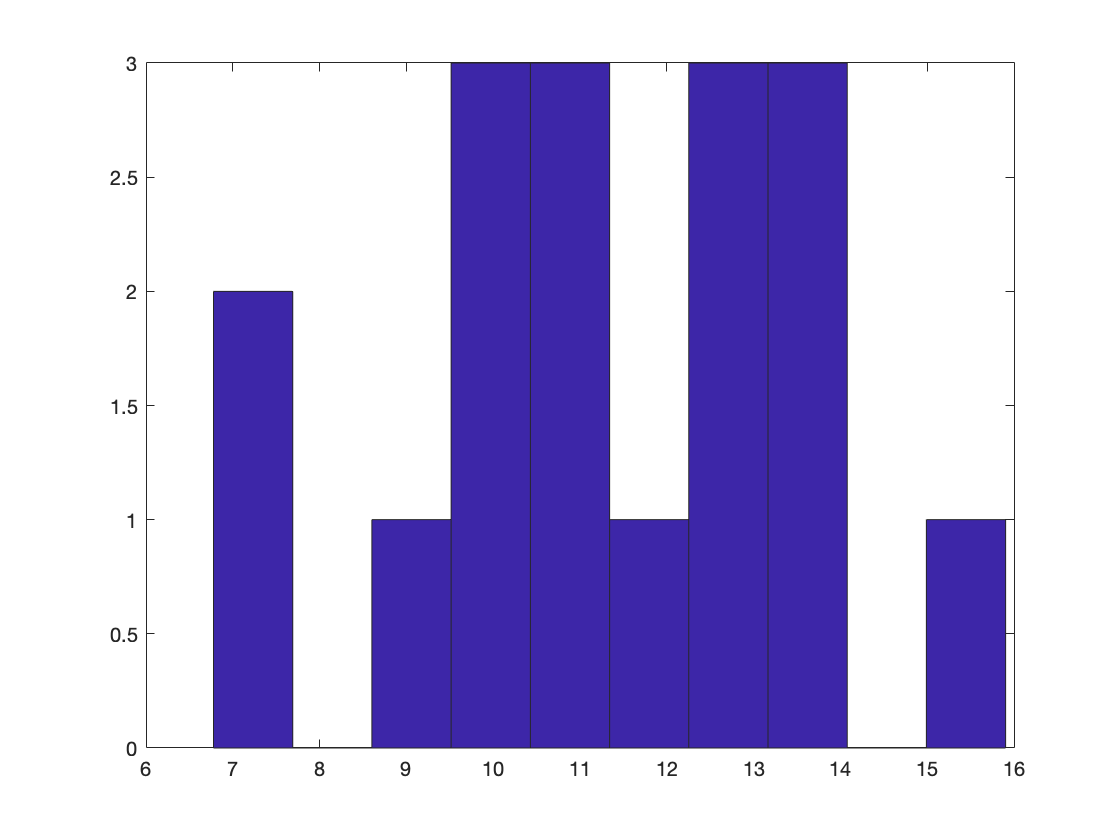

% first make some data points to use via the randn command
% plot it in a histogram to take a look.
x=2.5*randn(17,1)+10;

figure;hist(x,10)

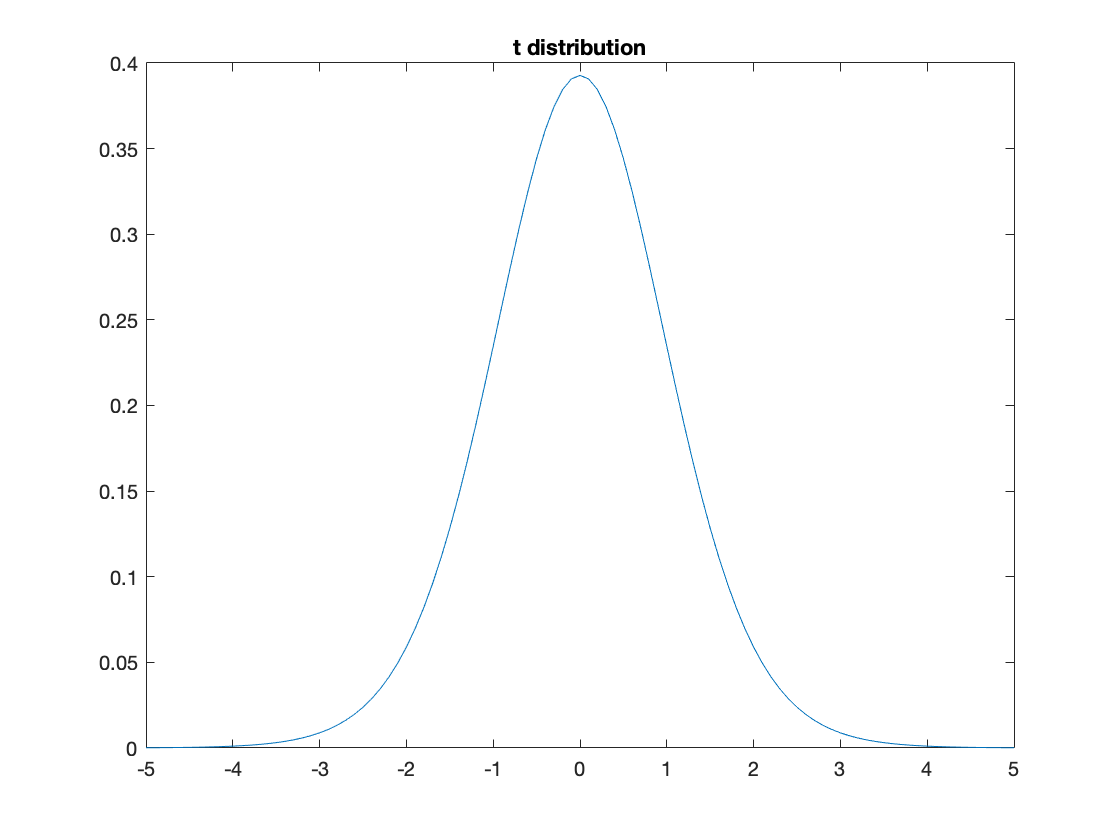


% Let's say the test we are trying to accomplish it to see if the data is
% consistent with a population mean of 10.  This will be our H0: mu=10.

% What's our Ha?  

% Let's say the alternative is that mu > 10, This means we will be looking
% for our test statistic in a rejection region which is out to the right
% side of the distribution.  So we will need the option for right tail.

%Quickly jump over to chapter 18-13.  Sampling distribution which is true
%under H0.

% What's our t distribution look like?

tdistr=tpdf(-5:.1:5,numel(x)-1);
figure; plot(-5:.1:5,tdistr)
title('t distribution')


% what's our t value and where is it on the distribution?  What do you predict for the result of
% the test?

obs_t=(mean(x)-10)/(std(x)/sqrt(numel(x)))

obs_t = 2.3061


% matlab's t-test function is called ttest

% do the ttest:

[h,p,ci,stats]=ttest(x,10,'alpha',0.05,'Tail','right');

% The main outputs are h and p.  p is the p value like we saw before with the
% permutation test.  it's the probability of obtaining a value of your test
% statistic that is as extreme or more extreme than our observed value. h
% is 0 or 1.  1: Reject H0! 0: Can't Reject!

% just for funsies:  How often do we make a type I error?  It's
% easy to estimate for type I here.  We know mu.  Above. It's 10.

% So what's a type I error again?  H0 rejected when it's true.
% In our case H0 is true.
% let's generate a sample and do the test lot's of times to see how often
% we reject H0.

N_iter=20000;
h_out=0;
for i=1:N_iter
    x=2.5*randn(17,1)+10;
    [h,p]=ttest(x,10,'alpha',0.05,'Tail','right');
    h_out=h_out+h;
end

% So what's the rate of type I error

h_out/N_iter

ans = 0.0522


% It should be close to our significance level!  If H0 is true and we
% reject the Null we are out in the tail of distribution by chance.  And
% alpha is the probability of that!

% Ok that's all for now.  Go back to slides.

## Try a two sample t test

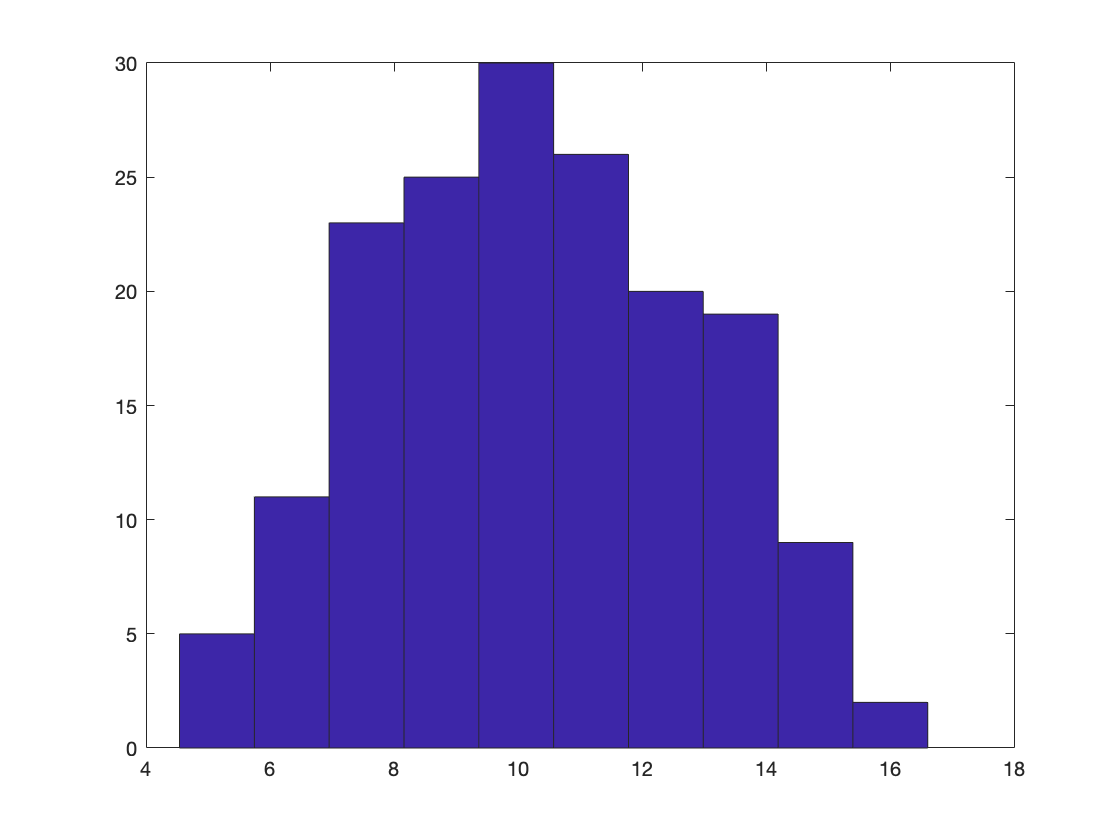

% first make 2 samples

x=2.5*randn(170,1)+10;
y=2.5*randn(340,1)+11;

% Look at them.

figure;hist(x,10);

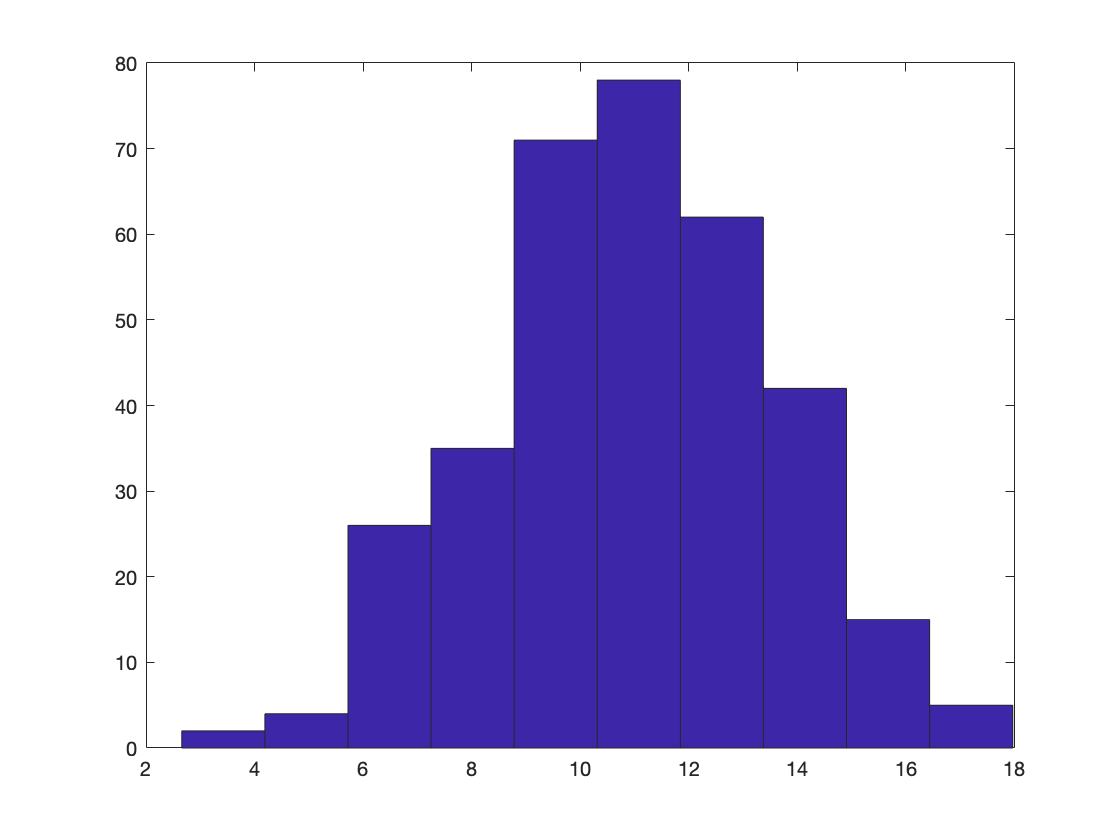

figure;hist(y,10);

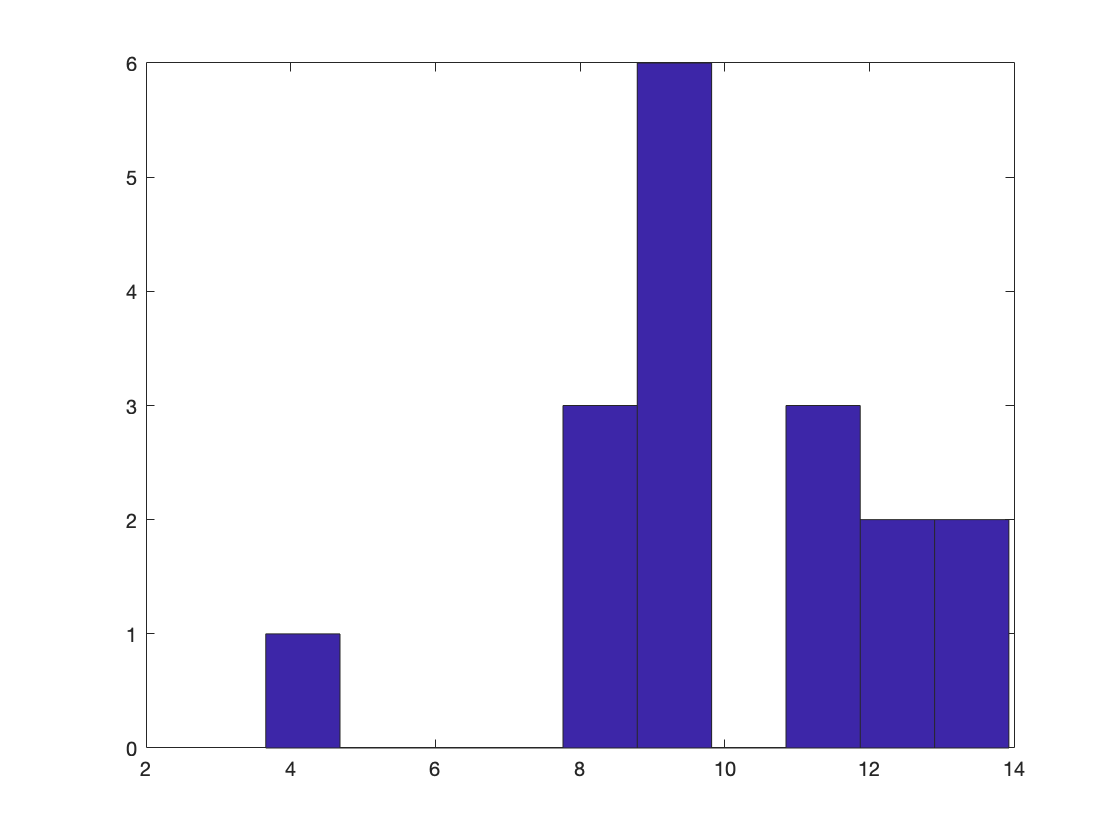


% very cute, but let's reduce the number of data points to make this a
% little more messy, I mean realistic.

x=2.5*randn(17,1)+10;
y=2.5*randn(34,1)+11;

% Look at them.

figure;hist(x,10);

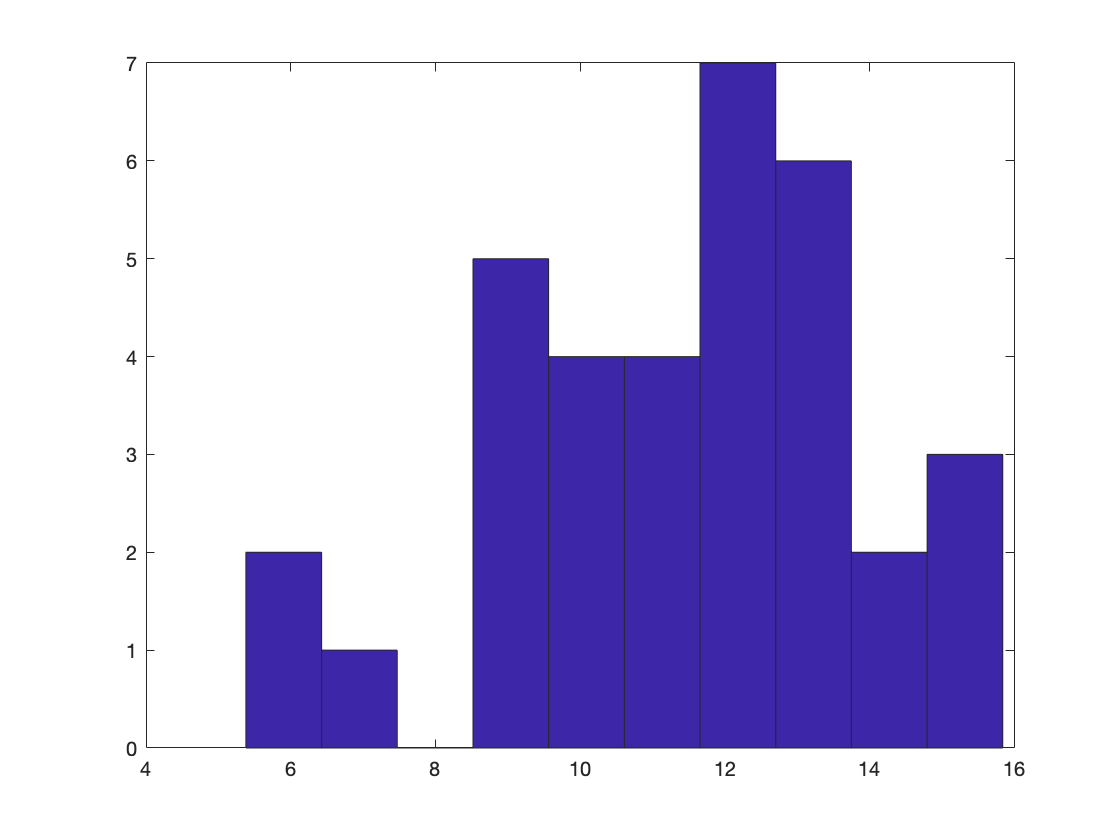

figure;hist(y,10);


% Here I made the variances equal.  In practice if we are using a two
% sample t test and allowing ourselves to assume equal variances then we
% compute what is called the pooled standard deviation.  

sp=((numel(x)-1)*std(x).^2+(numel(y)-1)*std(y).^2)/(numel(x)+numel(y)-2);
sp=sqrt(sp)

sp = 2.4691


% and then we need to think about our H0 for a moment.

% let's say our H0 is that the population means are equal.  ie mu1=mu2.  So
% we can calculate our t statistic as follows:

obs_t=(mean(x)-mean(y))/sqrt((sp.^2)/numel(x)+(sp.^2)/numel(y))

obs_t = -1.9529

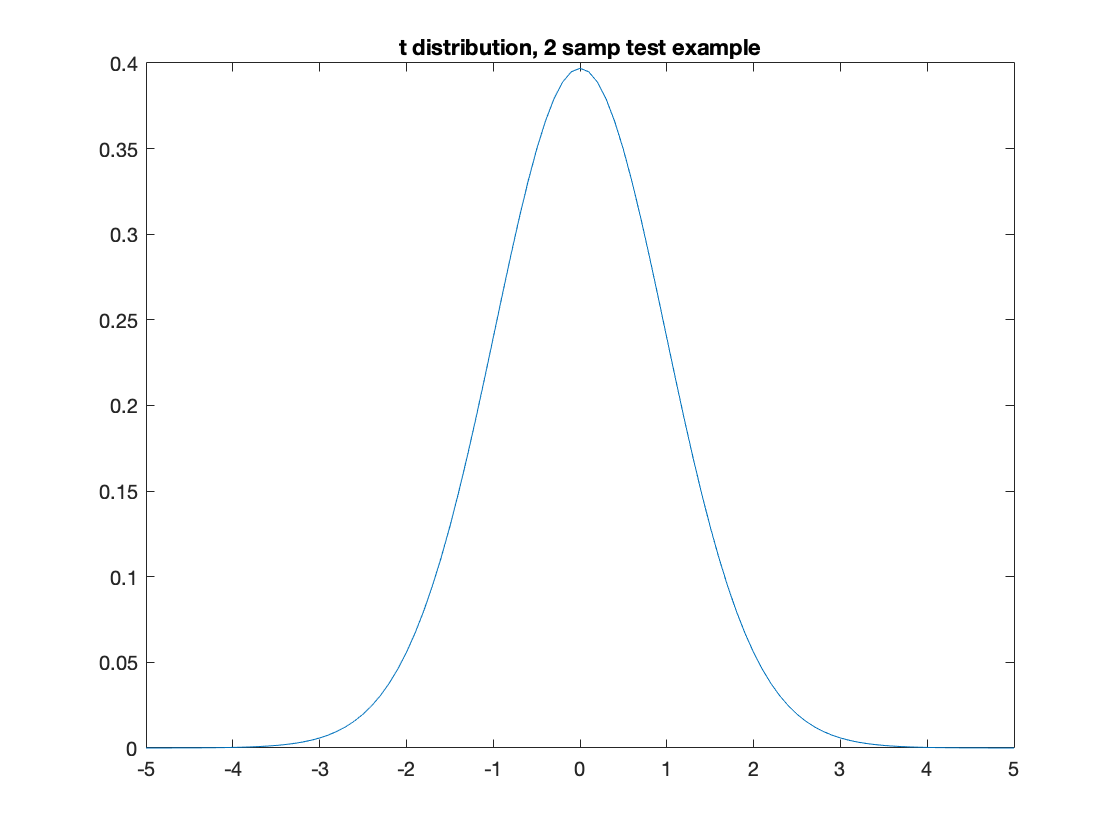


% Now we need to think about our Ha.  Let's say we thought it might be the
% case that mu1 < mu2, That means our t stat would be out there in the left
% tail of the distribution.  Think about an extreme case where we would feel confident
% in saying mu1 < mu2.  Imagine mu1 was 0 and
% mu2 was 1000.  If the samples were large and xbar ~mu1 and ybar ~mu2 then
% tstat would be large and negative! This means to the left.

% ok so what does our t distribution look like?  Where does our observed
% value of t land?  What does that imply for our testing?

tdistr=tpdf(-5:.1:5,numel(x)+numel(y)-2);
figure; plot(-5:.1:5,tdistr)
title('t distribution, 2 samp test example')



% Ok now use the matlab test to confirm our suspicions.

[h,p,ci,stats]=ttest2(x,y,'tail','left','vartype','equal')

h = 1

p = 0.0283

ci =       -Inf
   -0.2027


stats = struct with fields:
    tstat: -1.9529
       df: 49
       sd: 2.4691



% Note the test can also be done without assuming the variances are equal

% In this case the t stat is a bit easier to calculate, just as we had in
% the presentation.  No pooled sd.  However the dof is approxiamte and is
% estimated from the data using a formula you can look up.

[h,p,ci,stats]=ttest2(x,y,'tail','left','vartype','unequal')

h = 1

p = 0.0304

ci =       -Inf
   -0.1838


stats = struct with fields:
    tstat: -1.9438
       df: 31.7134
       sd: [2×1 double]



% Due to this approximation the test stat is only approximately t
% distributed so you only get approximately alpha significance.

% back to slides for a moment

## paired test!

% ok we need two samples again.

x=2.5*randn(17,1)+10;
y=2.5*randn(17,1)+11;

% same number of data points this time.

% ok, so what are our diffs?

the_diffs=x-y;

% What's our H0.  Let's say it is that the means are equal again.

% what's our t stat?

obs_t=mean(the_diffs)/(std(the_diffs)/sqrt(numel(the_diffs)))

obs_t = -1.9780

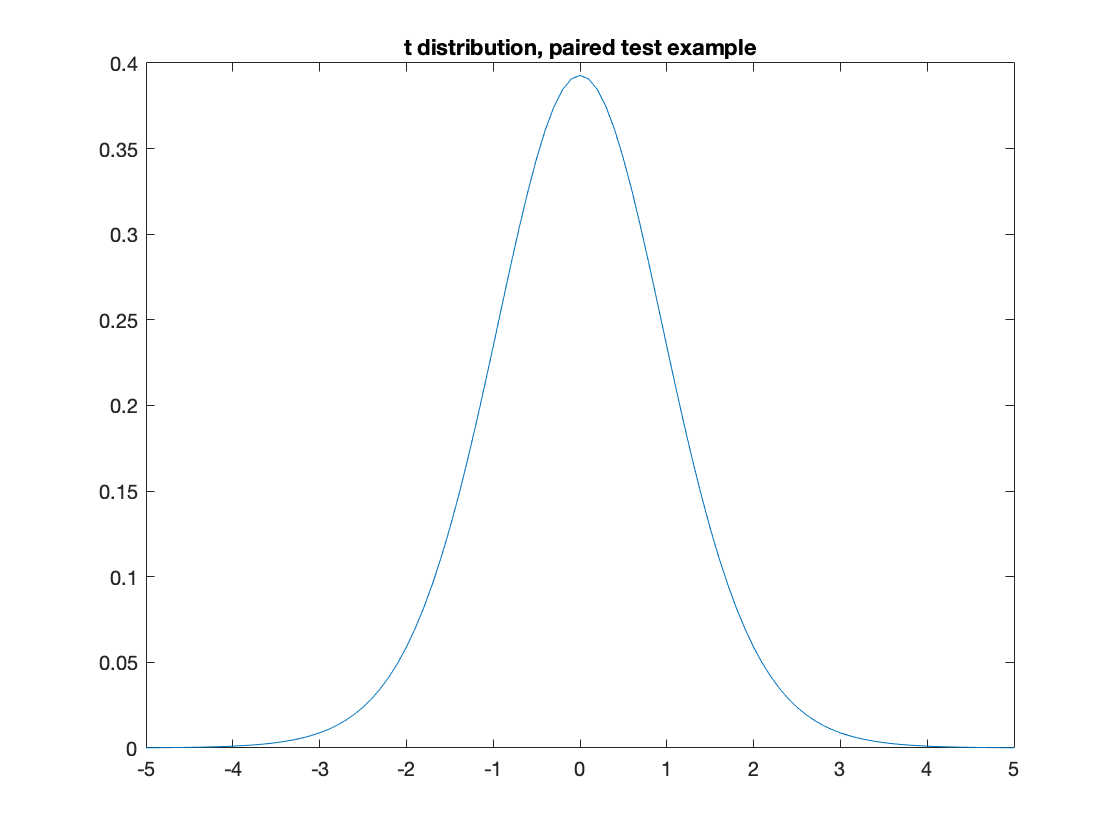


% what does our t distribution look like? Where is our observed t value?
% What's the likely outcome of our test?

tdistr=tpdf(-5:.1:5,numel(the_diffs)-1);
figure; plot(-5:.1:5,tdistr)
title('t distribution, paired test example')


% What's our Ha?  Let's say again that mu1<mu2, so we need to look at a
% rejection region in the left tail of the distribution.

% ok do the test.  it's ttest again

[h,p,ci,stats]=ttest(x,y,'tail','left');

## 1 sample ks-test example

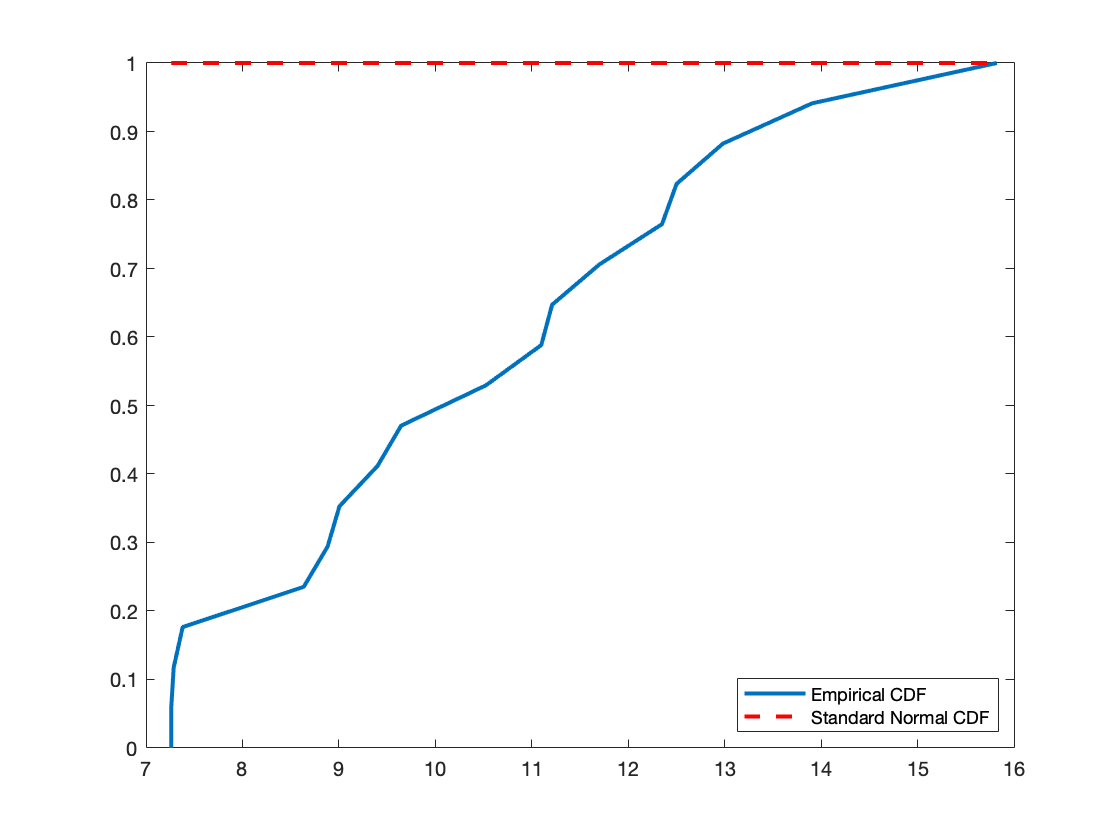

x=2.5*randn(17,1)+10;

figure;
[f,x_values] = ecdf(x);
J = plot(x_values,f);
hold on;
K = plot(x_values,normcdf(x_values),'r--');
set(J,'LineWidth',2);
set(K,'LineWidth',2);
legend([J K],'Empirical CDF','Standard Normal CDF','Location','SE');